## Clear ALL

close all
clear all
clc

## Define Data

ratio = [3.5333 2.20833 1.43333 1.34146 1 .807018 1.28814 1.2881 4.2727 3.3571]'; % [-] - Single Ratio
Oratio = [15.096730 9.4355315 6.124189 4.5034153 3.3571 3.3571 2.7092401 15.279454]'; % [-] - Overall Ratio
Zp = [15 24 30 41 47 57 59 59 11 14]'; % [-] - Pinion Teeth Number
Zg = [53 53 43 55 47 46 76 76 47 47]'; % [-] Gear Teeth Number
m = [3 2.5 2.5 2.5 2.5 2.5 2.5 2.5 4 4]'; % [mm] - Normal Module
alpha = [22.5 25 25 25 22.5 25 25 25 25 25]'; % [deg] - Normal Pressure Angle
psi = [22 29 34 31 33 23 31.5 31.5 34 34]'; % [deg] - Helix Angle
Rp = [24.2647 34.2857 45.2055 59.7917 70 77.4757 86.5201 86.5201 26.6 33.8]'; % [mm] - Pinion Radius
Rg = [85.7353 75.7143 64.7945 80.2083 70 63.5243 86.5201 111.45 113.4 113.4]'; % [mm] - Gear Radius
b = [30 20.5 20 17 18 17 15 15 46 46]'; % [mm] - Facewidth
Zc = [206.98 35.25 164.83 112.92 177.92 35 248.73 297.92 360 409.19]; % [mm] - Distance

## Define Main Parameters

C_main = 361; % [Nm] - Input Torque
L1 = 415; % [mm] - Primary Shaft Length
L2 = 507.9; % [mm] - Secondary Shaft Length
Zd1 = 300; % [mm] - Primary Bearing Distance
Zd2 = L2-50; % [mm] - Secondary Bearing Distance

## Gear Forces

First, we calculate the torque corresponding to each gear:


$$C_i =C_{\textrm{main}} *\tau_i$$


Second, we calculate the tangential force on the selected gear and the final drive:

$F_{t,i} =\frac{C_i }{R_{G,i} }$   ;   $F_{t,\textrm{FD}} =\frac{C_i }{R_{P,\textrm{FD}} }$

Finally, we calculate the radial and axial forces on the selected gear and the final drive:

$F_{r,i} =F_{t,i} *\frac{\tan \left(\alpha_i \right)}{\cos \left(\psi_i \right)}$   ;   $F_{a,i} =F_{t,i} *\tan \left(\psi_i \right)$

$F_{r,\textrm{FD}} =F_{t,\textrm{FD}} *\frac{\tan \left(\alpha_{\textrm{FD}} \right)}{\cos \left(\psi_{\textrm{FD}} \right)}$   ;   $F_{a,\textrm{FD}} =F_{t,\textrm{FD}} *\tan \left(\psi_{\textrm{FD}} \right)$

**NB: When the rear gear is selected, on the primary shaft the first gear acts as the input gear and the rear acts as the overdrive.**

C = C_main*ratio; % [Nm] - Torque on Gear
for k = 1:8
    Ft(k, 1) = C(k)/(Rg(k)*1e-3); % [N] - Tangential Force on Gear
    Fr(k, 1) = Ft(k, 1)*tand(alpha(k))/cosd(psi(k)); % [N] - Radial Force on Gear
    Fa(k, 1) = Ft(k, 1)*tand(psi(k)); % [N] - Axial Force on Gear
    if k<4
        Ft(k, 2) = C(k)/(Rp(end-1)*1e-3); % [N] - Tangential Force on FD1
        Fr(k, 2) = Ft(k, 2)*tand(alpha(end-1))/cosd(psi(end-1)); % [N] - Radial Force on FD1
        Fa(k, 2) = Ft(k, 2)*tand(psi(end-1)); % [N] - Axial Force on FD1
    elseif (k>=4 && k<7) || (k==8)
        Ft(k, 2) = C(k)/(Rp(end)*1e-3); % [N] - Tangential Force on FD2
        Fr(k, 2) = Ft(k, 2)*tand(alpha(end))/cosd(psi(end)); % [N] - Radial Force on FD2
        Fa(k, 2) = Ft(k, 2)*tand(psi(end)); % [N] - Axial Force on FD2
    else
        Ft(k, 1) = Ft(1, 1); % [N] - Tangential Force on G1
        Ft(k, 2) = C(k)/(Rp(k)*1e-3); % [N] - Tangential Force on R1
        Fr(k, 1) = Fr(1, 1); % [N] - Radial Force on G1
        Fr(k, 2) = Ft(k, 2)*tand(alpha(k))/cosd(psi(k)); % [N] - Radial Force on R1
        Fa(k, 1) = Fa(1, 1); % [N] - Axial Force on G1
        Fa(k, 2) = Ft(k, 2)*tand(psi(k)); % [N] - Axial Force on R2;
    end
end

## Reactions on Bearings

By applying the summation of forces and moments in two different planes, we can find the reaction forces in the bearings:


$$R_{z,L} =F_{a,\textrm{FD}} -F_{a,i}$$



$$R_{y,R} =\frac{F_{t,\textrm{FD}} *Z_{c,\textrm{FD}} -F_{t,i} *Z_{c,i} }{Z_d }$$



$$R_{y,L} =F_{t,\textrm{FD}} -F_{t,i} -R_{y,R}$$



$$R_{x,R} =\frac{F_{a,\textrm{FD}} *R_{P,\textrm{FD}} -\left(F_{r,\textrm{FD}} *Z_{c,\textrm{FD}} +F_{a,i} *R_{G,i} +F_{r,i} *Z_{c,i} \right)}{Z_d }$$



$$R_{x,L} =-\left(F_{r,i} +F_{r,\textrm{FD}} +R_{x,R} \right)$$


for k = 1:8
    if k<4
        Ry_r(k, 1) = (Ft(k, 2)*Zc(end-1) - Ft(k ,1)*Zc(1))/Zd1; % [N] - Right Primary Bearing Y Reaction
        Ry_r(k, 2) = 0; % [N] - Right Seconday Bearing Y Reaction;
        Rx_r(k, 1) = (Fa(k, 2)*Rp(end-1) - (Fr(k, 2)*Zc(end-1) - Fa(k, 1)*Rg(k) - Fr(k, 1)*Zc(k)))/Zd1; % [N] - Right Primary Bearing X Reaction
        Rx_r(k, 2) = 0; % [N] - Right Secondary Bearing X Reaction
        Rz_l(k, 1) = Fa(k, 2) - Fa(k, 1); % [N] - Left Primary Bearing Z Reaction
        Rz_l(k, 2) = 0; % [N] - Left Seconday Bearing Z Reaction
        Ry_l(k, 1) = Ft(k, 2) - Ft(k, 1) - Ry_r(k, 1); % [N] - Left Primary Bearing Y Reaction
        Ry_l(k, 2) = 0; % [N] - Left Seconday Bearing Y Reaction
        Rx_l(k, 1) = -(Fr(k, 1) + Fr(k, 2) + Rx_r(k, 1)); % [N] - Left Primary Bearing X Reaction
        Rx_l(k, 2) = 0; % [N] - Left Seconday Bearing X Direction
    elseif (k>=4 && k<7) || (k==8)
        Ry_r(k, 2) = (Ft(k, 2)*Zc(end) - Ft(k ,1)*Zc(k))/Zd2; % [N] Right Seconday Bearing Y Reaction
        Ry_r(k, 1) = 0; % [N] - Right Primary Bearing Y Reactions
        Rx_r(k, 2) = (Fa(k, 2)*Rp(end) - (Fr(k, 2)*Zc(end) + Fa(k, 1)*Rg(k) + Fr(k, 1)*Zc(k)))/Zd2; % [N] - Right Seconday Bearing X Reaction
        Rx_r(k, 1) = 0; % [N] - Right Primary Bearing X Reaction
        Rz_l(k, 2) = Fa(k, 2) - Fa(k, 1); % [N] - Left Seconday Bearing Z Reaction
        Rz_l(k, 1) = 0; % [N] - Left Primary Bearing Z Reaction
        Ry_l(k, 2) = Ft(k, 2) - Ft(k, 1) - Ry_r(k, 2); % [N] - Left Seconday Bearing Y Reaction
        Ry_l(k, 1) = 0; % [N] - Left Primary Bearing Y Reaction
        Rx_l(k, 2) = -(Fr(k, 1) + Fr(k, 2) + Rx_r(k, 2)); % [N] - Left Secondary Bearing X Reaction
        Rx_l(k, 1) = 0; % [N] - Left Primary Bearing X Reaction
    else
        Ry_r(k, 1) = (Ft(k, 2)*Zc(k) - Ft(k, 1)*Zc(1))/Zd1; % [N] - Right Primary Bearig Y Reaction
        Ry_r(k, 2) = (Ft(k+1, 2)*Zd2 - Ft(k+1, 1)*Zc(k+1))/Zd2; % [N] - Right Seconday Bearing Y Reaction
        Rx_r(k, 1) = (Fa(k, 2)*Rp(k) - Fr(k, 1)*Zc(1) - Fa(k, 1)*Rg(1) - Fr(k, 2)*Zc(k))/Zd1; % [N] - Right Primary Bearing X Reaction
        Rx_r(k, 2) = (Fa(k+1, 2)*Rp(end) - (Fr(k, 2)*Zd2 + Fa(k+1, 1)*Rg(k+1) + Fr(k+1)*Zc(k+1)))/Zd2; % [N] - Right Seconday Bearing X Reaction
        Rz_l(k, 1) = Fa(k, 2) - Fa(k, 1); % [N] - Left Primary Bearing Z Reaction
        Rz_l(k, 2) = Fa(k+1, 2) - Fa(k+1, 1); % [N] - Left Secondary Bearing Z Reaction
        Ry_l(k, 1) = Ft(k, 2) - Ft(k, 1) - Ry_r(k, 1); % [N] - Left Primary Bearing Y Reaction
        Ry_l(k, 2) = 0; % [N] - Left Secondary Bearing Y Reaction
        Rx_l(k, 1) = -(Fr(k, 1) + Fr(k, 2) + Rx_r(k, 1)); % [N] - Left Primary Bearing X Reaction
        Rx_l(k, 2) = 0; % [N] - Left Secondary Bearing X Reaction
    end
end

## Loads along The Shaft

The loads considered along the shaft cross-section are the axial force, bending moments around **X-axis** and **Y-axis**, shear forces along **X-axis** and **Y-axis, **and torisional moment around **Z-axis**. As ***z*** varies from zero till the length of the shaft, the considered equations are:

- 
$$z\le 25$$


   
$$N=T_{\textrm{xz}} =T_{\textrm{yz}} =M_{\textrm{xx}} =M_{\textrm{yy}} =M_{\textrm{zz}} =0$$


- $25\le z<Z_{c,i}$+25


$$N=-R_{z,L}$$



$$T_{\textrm{yz}} =-R_{y,L}$$



$$T_{\textrm{xz}} =-R_{x,L}$$



$$M_x =T_{\textrm{yz}} *\left(z-25\right)$$



$$M_y =-T_{\textrm{xz}} *\left(z-25\right)$$



$$M_z =0$$


- 
$$Z_{c,i} +25\le z<Z_{c,\textrm{FD}} +25$$



$$N=-\left(R_{z,L} +F_{a,i} \right)$$



$$T_{\textrm{yz}} =-\left(R_{y,L} +F_{t,i} \right)$$



$$T_{\textrm{xz}} =-\left(R_{x,L} +F_{r,i} \right)$$



$$M_x =F_{t,i} *Z_{c,i} +T_{\textrm{yz}} *\left(z-25\right)$$



$$M_y =-\left\lbrack F_{r,i} *Z_{c,i} +T_{\textrm{yz}} *\left(z-25\right)\right\rbrack$$



$$M_z =F_{t,i} *R_{G,i}$$


- 
$$Z_{c,\textrm{Fd}} +25\le z\le Z_d +25$$



$$N=F_{a,\textrm{FD}} -\left(F_{a,i} +R_{z,L} \right)$$



$$T_{\textrm{yz}} =F_{t,\textrm{FD}} -\left(F_{t,i} +R_{y,L} \right)$$



$$T_{\textrm{xz}} =-\left(F_{r,\textrm{FD}} +F_{r,i} +R_{x,L} \right)$$



$$M_x =\left\lbrack F_{t,i} *Z_{c,i} -F_{t,\textrm{FD}} *Z_{c,i} +T_{\textrm{yz}} *\left(z-25\right)\right\rbrack$$



$$M_y =-\left\lbrack F_{r,i} *Z_{c,i} +F_{a,i} *R_{G,i} +F_{r,\textrm{FD}} *Z_{c,\textrm{FD}} -F_{a,\textrm{FD}} *R_{P,\textrm{FD}} +T_{\textrm{xz}} *\left(z-25\right)\right\rbrack$$



$$M_z =0$$


**NB: 25 mm is the offset of the left bearing from the start of the shaft.**

z1 = 0:0.1:L1; % [mm] - Z Vector Along Primary Shaft
z2 = 0:0.1:L2; % [mm] - Z Vector Along Secondary Shaft
N = zeros(length(z2), 8, 2); % [N] - Axial Load Across Z Cross-Section
Tyz = zeros(length(z2), 8, 2); % [N] - YZ-Plane Shear Load Across Z Cross-Section
Txz = zeros(length(z2), 8, 2); % [N] - XZ-Plane Shear Load Across Z Cross-Section
Mx = zeros(length(z2), 8, 2); % [Nmm] - Bending Moment Around X-Axis Across Z Cross-Section
My = zeros(length(z2), 8, 2); % [Nmm] - Benging Moment Around Y-Axis Across Z Cross-Section
Mz = zeros(length(z2), 8, 2); % [Nmm] - Torsional Moment Around Z-Axis Across Z Cross-Section

for k = 1:8
    if k<4
        for j = 1:length(z1)
            if z1(j)>=25 && z1(j)<Zc(k)+25
                N(j, k, 1) = -Rz_l(k, 1);
                Tyz(j, k, 1) = -Ry_l(k, 1);
                Txz(j, k, 1) = -Rx_l(k, 1);
                Mx(j, k, 1) = Tyz(j, k, 1)*(z1(j)-25);
                My(j, k, 1) = -Txz(j, k, 1)*(z1(j)-25);
            elseif z1(j)>=Zc(k)+25 && z1(j)<Zd1+25
                N(j, k, 1) = -(Rz_l(k, 1) + Fa(k, 1));
                Tyz(j, k, 1) = -(Ry_l(k, 1) + Ft(k, 1));
                Txz(j, k, 1) = -(Rx_l(k, 1) + Fr(k, 1));
                Mx(j, k, 1) = Ft(k, 1)*Zc(k) + Tyz(j, k, 1)*(z1(j)-25);
                My(j, k, 1) = -(Fr(k, 1)*Zc(k) + Fa(k, 1)*Rg(k) + Txz(j, k, 1)*(z1(j)-25));
                %Mz(j, k, 1) = Ft(k, 1)*Rg(k);
            elseif z1(j)>=Zd1+25 && z1(j)<=Zc(end-1)+25
                N(j, k, 1) = -(Fa(k, 1) + Rz_l(k, 1));
                Tyz(j, k, 1) = -(Ft(k, 1) + Ry_l(k, 1)+ Ry_r(k, 1));
                Txz(j, k, 1) = -(Rx_r(k, 1) + Fr(k, 1) + Rx_l(k, 1));
                Mx(j, k, 1) = (Ft(k, 1)*Zc(k) + Ry_r(k, 1)*Zd1 + Tyz(j, k, 1)*(z1(j)-25));
                My(j, k, 1) = -(Fr(k, 1)*Zc(k) + Fa(k, 1)*Rg(k) + Rx_r(k, 1)*Zd1 + Txz(j, k, 1)*(z1(j)-25));
            end
            
            if z1(j)>=Zc(k)+b(k)/2+35 && z1(j)<=Zc(end-1)+25
                Mz(j, k, 1) = Ft(k, 1)*Rg(k);
            end
        end
    elseif (k>=4 && k<7) || (k==8)
        for j = 1:length(z2)
            if z2(j)>=25 && z2(j)<Zc(k)+25
                N(j, k, 2) = -Rz_l(k, 2);
                Tyz(j, k, 2) = -Ry_l(k, 2);
                Txz(j, k, 2) = -Rx_l(k, 2);
                Mx(j, k, 2) = Tyz(j, k, 2)*(z2(j)-25);
                My(j, k, 2) = -Txz(j, k, 2)*(z2(j)-25);
            elseif z2(j)>=Zc(k)+25 && z2(j)<Zc(end)+25
                N(j, k, 2) = -(Rz_l(k, 2) + Fa(k, 1));
                Tyz(j, k, 2) = -(Ry_l(k, 2) + Ft(k, 1));
                Txz(j, k, 2) = -(Rx_l(k, 2) + Fr(k, 1));
                Mx(j, k, 2) = Ft(k, 1)*Zc(k) + Tyz(j, k, 2)*(z2(j)-25);
                My(j, k, 2) = -(Fr(k, 1)*Zc(k) + Fa(k, 1)*Rg(k) + Txz(j, k, 2)*(z2(j)-25));
                %Mz(j, k, 2) = Ft(k, 1)*Rg(k);
            elseif z2(j)>=Zc(end)+25 && z2(j)<=ceil(Zd2+25)
                N(j, k, 2) = Fa(k, 2) - (Fa(k, 1) + Rz_l(k, 2));
                Tyz(j, k, 2) = Ft(k, 2) - (Ft(k, 1) + Ry_l(k, 2));
                Txz(j, k, 2) = -(Fr(k, 2) + Fr(k, 1) + Rx_l(k, 2));
                Mx(j, k, 2) = (Ft(k, 1)*Zc(k) - Ft(k, 2)*Zc(end) + Tyz(j, k, 2)*(z2(j)-25));
                My(j, k, 2) = -(Fr(k, 1)*Zc(k) + Fa(k, 1)*Rg(k) + Fr(k, 2)*Zc(end) - Fa(k, 2)*Rg(end) + Txz(j, k, 2)*(z2(j)-25));
                
            end
            
            if z2(j)>=Zc(k)+b(k)/2+35 && z2(j)<=Zc(end)+25
                Mz(j, k, 2) = Ft(k, 1)*Rg(k);
            end
        end
    else
        for j = 1:length(z1)
            if z1(j)>=25 && z1(j)<Zc(1)+25
                N(j, k, 1) = -Rz_l(k, 1);
                Tyz(j, k, 1) = -Ry_l(k, 1);
                Txz(j, k, 1) = -Rx_l(k, 1);
                Mx(j, k, 1) = Tyz(j, k, 1)*(z1(j)-25);
                My(j, k, 1) = -Txz(j, k, 1)*(z1(j)-25);
            elseif z1(j)>=Zc(1)+25 && z1(j)<Zc(k)+25
                N(j, k, 1) = -(Rz_l(k, 1) + Fa(k, 1));
                Tyz(j, k, 1) = -(Ry_l(k, 1) + Ft(k, 1));
                Txz(j, k, 1) = -(Rx_l(k, 1) + Fr(k, 1));
                Mx(j, k, 1) = Ft(k, 1)*Zc(1) + Tyz(j, k, 1)*(z1(j)-25);
                My(j, k, 1) = -(Fr(k, 1)*Zc(1) + Fa(k, 1)*Rg(1) + Txz(j, k, 1)*(z1(j)-25));
                %Mz(j, k, 1) = Ft(k, 1)*Rg(1);
            elseif z1(j)>=Zc(k)+25 && z1(j)<=Zd1+25
                N(j, k, 1) = Fa(k, 2) - (Rz_l(k, 1) + Fa(k, 1));
                Tyz(j, k, 1) = Ft(k, 2) - (Ry_l(k, 1) + Ft(k, 1));
                Txz(j, k, 1) = -(Rx_l(k, 1) + Fr(k, 1) + Fr(k, 2));
                Mx(j, k, 1) = Ft(k, 1)*Zc(1) + Ft(k, 2)*Zc(k) + Tyz(j, k, 1)*(z1(j)-25);
                My(j, k, 1) = Ft(k, 2)*Zc(k) - (Fr(k, 1)*Zc(1) + Fa(k, 1)*Rg(1) + Fr(k, 1)*Rp(k) + Txz(j, k, 1)*(z1(j)-25));
            end
            
            if z1(j)>=Zc(1)+25 && z1(j)<=Zc(k)+25
            Mz(j, k, 1) = Ft(k, 1)*Rg(1);
            end
        end
    end
end

We can also define:

$M_f =\sqrt{M_x^2 +M_y^2 }$       ;       $T_f =\sqrt{T_{\textrm{xz}}^2 +T_{\textrm{yz}}^2 }$

Mf = sqrt(Mx.^2 + My.^2); % [Nmm] - Resultant Bending Moment
Tf = sqrt(Txz.^2 + Tyz.^2); % [N] - Resultant Shear Force

## Plot Loads

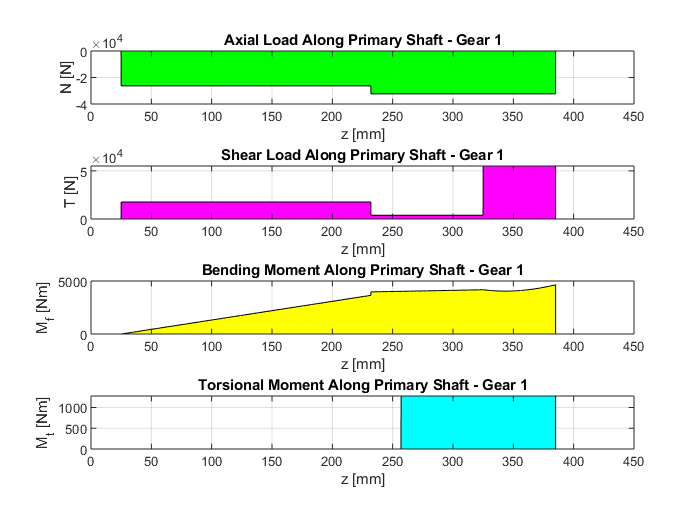

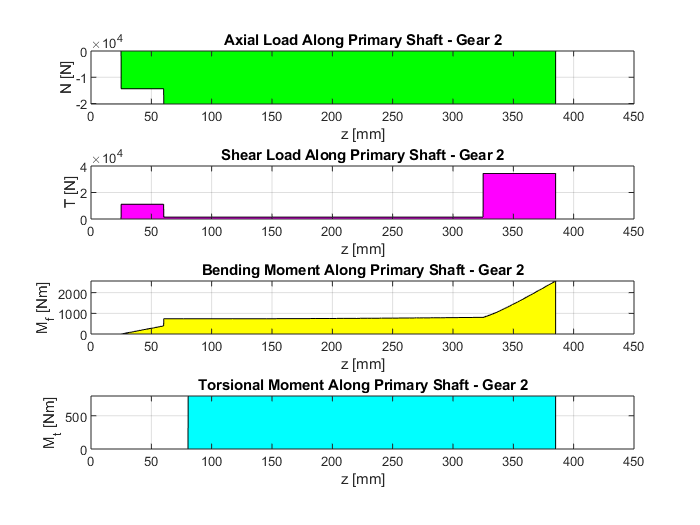

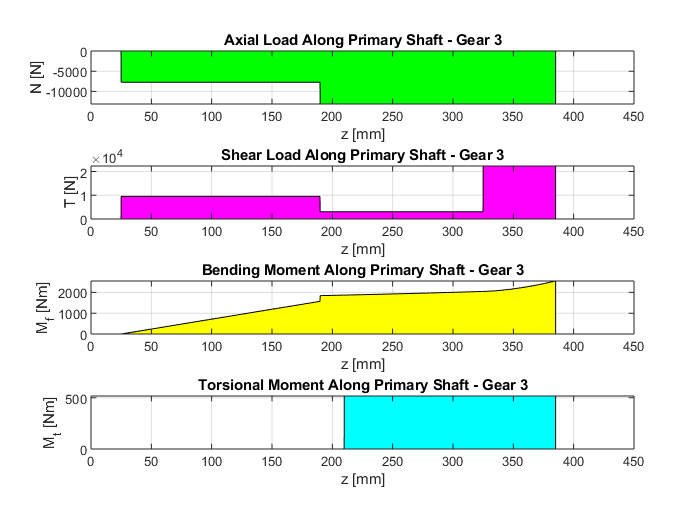

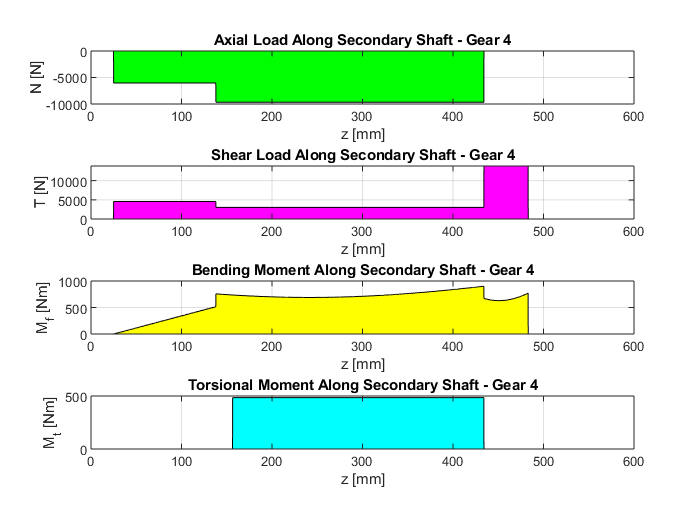

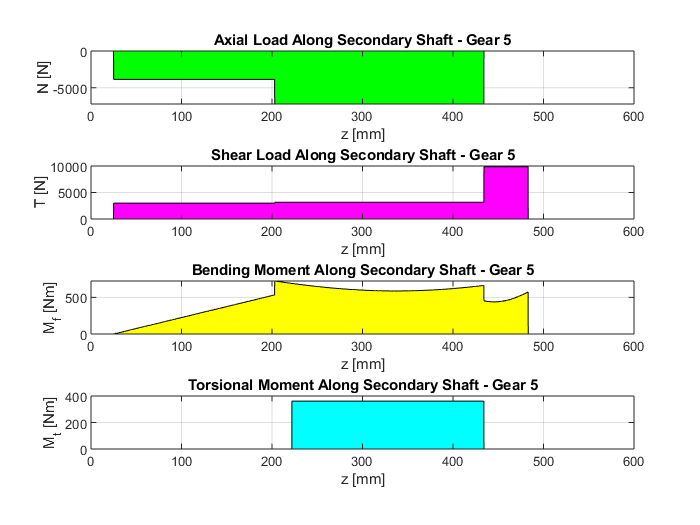

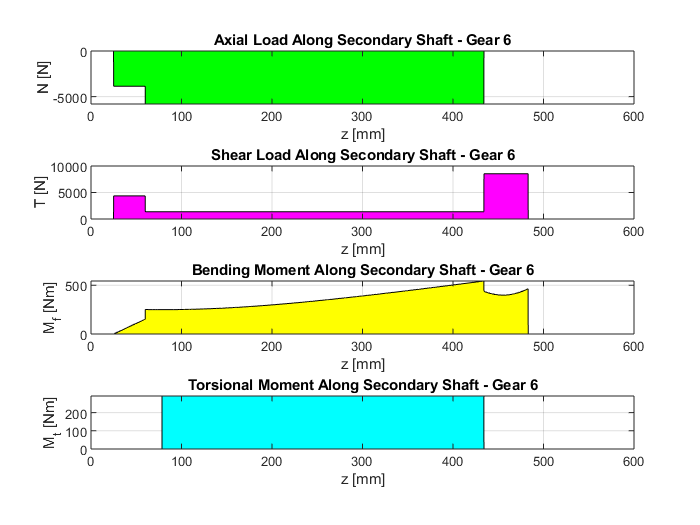

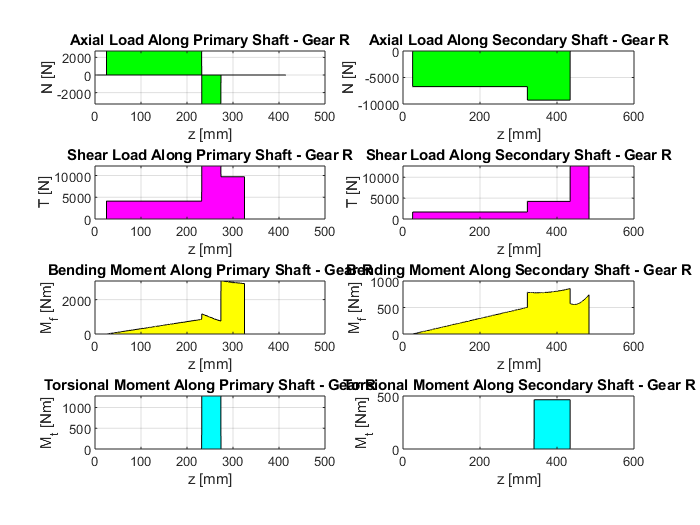

for k = 1:7
    figure(k)
    if k<4
        subplot(4, 1, 1)
        fill(z1, N(1:length(z1), k, 1), 'g')
        grid on
        xlabel('z [mm]')
        ylabel('N [N]')
        title(['Axial Load Along Primary Shaft - Gear ', num2str(k)])
        subplot(4, 1, 2)
        fill(z1, Tf(1:length(z1), k, 1), 'm')
        grid on
        xlabel('z [mm]')
        ylabel('T [N]')
        title(['Shear Load Along Primary Shaft - Gear ', num2str(k)])
        subplot(4, 1, 3)
        fill(z1,Mf(1:length(z1), k, 1)*1e-3, 'y')
        grid on
        xlabel('z [mm]')
        ylabel('M_f [Nm]')
        title(['Bending Moment Along Primary Shaft - Gear ', num2str(k)])
        subplot(4, 1, 4)
        fill(z1, Mz(1:length(z1), k, 1)*1e-3, 'c')
        grid on
        xlabel('z [mm]')
        ylabel('M_t [Nm]')
        title(['Torsional Moment Along Primary Shaft - Gear ', num2str(k)])
    elseif k>=4 && k<7
        subplot(4, 1, 1)
        fill(z2, N(:, k, 2), 'g')
        grid on
        xlabel('z [mm]')
        ylabel('N [N]')
        title(['Axial Load Along Secondary Shaft - Gear ', num2str(k)])
        subplot(4, 1, 2)
        fill(z2, Tf(:, k, 2), 'm')
        grid on
        xlabel('z [mm]')
        ylabel('T [N]')
        title(['Shear Load Along Secondary Shaft - Gear ', num2str(k)])
        subplot(4, 1, 3)
        fill(z2, Mf(:, k, 2)*1e-3, 'y')
        grid on
        xlabel('z [mm]')
        ylabel('M_f [Nm]')
        title(['Bending Moment Along Secondary Shaft - Gear ', num2str(k)])
        subplot(4, 1, 4)
        fill(z2, Mz(:, k, 2)*1e-3, 'c')
        grid on
        xlabel('z [mm]')
        ylabel('M_t [Nm]')
        title(['Torsional Moment Along Secondary Shaft - Gear ', num2str(k)])
    else
        figure(k)
        subplot(4, 2, 1)
        fill(z1, N(1:length(z1), k, 1), 'g')
        grid on
        xlabel('z [mm]')
        ylabel('N [N]')
        title('Axial Load Along Primary Shaft - Gear R')
        subplot(4, 2, 2)
        fill(z2, N(:, k+1, 2), 'g')
        grid on
        xlabel('z [mm]')
        ylabel('N [N]')
        title('Axial Load Along Secondary Shaft - Gear R')
        subplot(4, 2, 3)
        fill(z1, Tf(1:length(z1), k, 1), 'm')
        grid on
        xlabel('z [mm]')
        ylabel('T [N]')
        title('Shear Load Along Primary Shaft - Gear R')
        subplot(4, 2, 4)
        fill(z2, Tf(:, k+1, 2), 'm')
        grid on
        xlabel('z [mm]')
        ylabel('T [N]')
        title('Shear Load Along Secondary Shaft - Gear R')
        subplot(4, 2, 5)
        fill(z1, Mf(1:length(z1), k, 1)*1e-3, 'y')
        grid on
        xlabel('z [mm]')
        ylabel('M_f [Nm]')
        title('Bending Moment Along Primary Shaft - Gear R')
        subplot(4, 2, 6)
        fill(z2, Mf(:, k+1, 2)*1e-3, 'y')
        grid on
        xlabel('z [mm]')
        ylabel('M_f [Nm]')
        title('Bending Moment Along Secondary Shaft - Gear R')
        subplot(4, 2, 7)
        fill(z1, Mz(1:length(z1), k, 1)*1e-3, 'c')
        grid on
        xlabel('z [mm]')
        ylabel('M_t [Nm]')
        title('Torsional Moment Along Primary Shaft - Gear R')
        subplot(4, 2, 8)
        fill(z2, Mz(:, k+1, 2)*1e-3, 'c')
        grid on
        xlabel('z [mm]')
        ylabel('M_t [Nm]')
        title('Torsional Moment Along Secondary Shaft - Gear R')
    end
end

## Diameter Calculation

Based on:


$$\sigma_{\textrm{tot}} =\sqrt{\sigma_N^2 +3*\tau^2 }<\sigma_{\textrm{adm}} =\frac{\sigma_{\textrm{Rp},0\ldotp 2} }{\textrm{SF}}$$


where

$\sigma_N =\frac{N}{A}+\frac{M_f }{W_f }$     such that   $A=\pi *\frac{D^2 }{4}$     and $W_f =\pi *\frac{D^3 }{32}$

and

$\tau =\frac{M_z }{W_t }$       such that       $W_t =\pi *\frac{D^3 }{16}$

we can realize that


$$\pi^2 *{\left(\frac{\sigma_{\textrm{Rp},0\ldotp 2} }{\textrm{SF}}\right)}^2 *D^6 -16*N^2 *D^2 \;-256*N*M_f *D-256*\left(4*M_f^2 +3*M_z^2 \right)=0$$


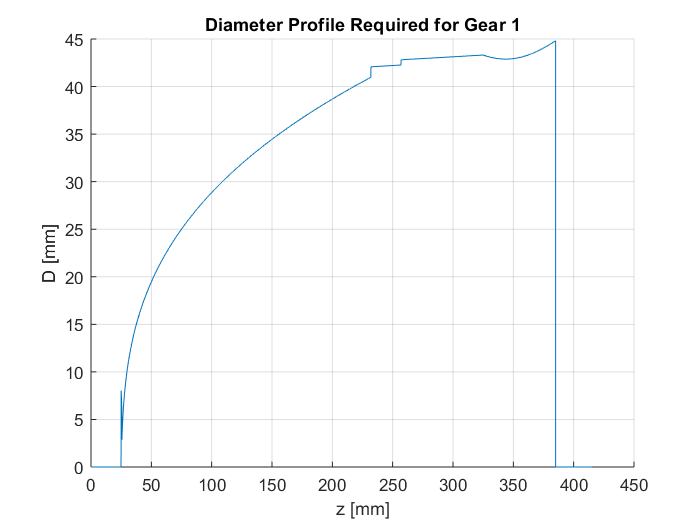

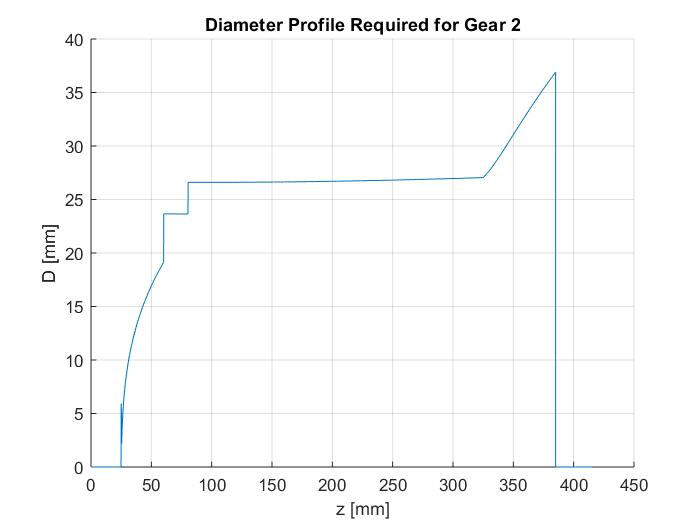

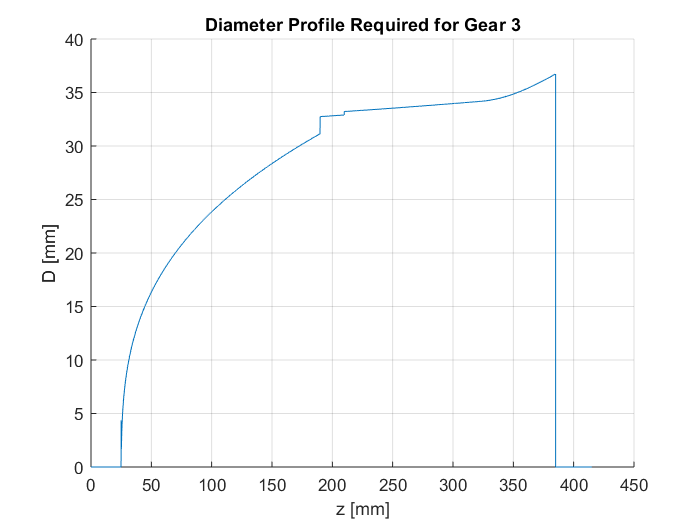

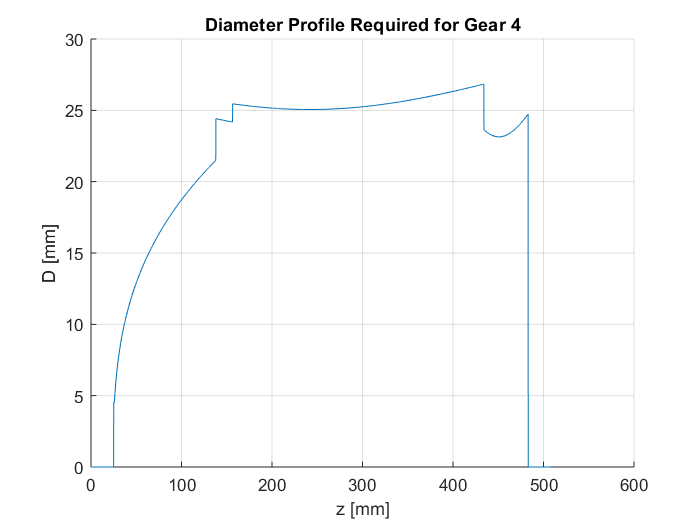

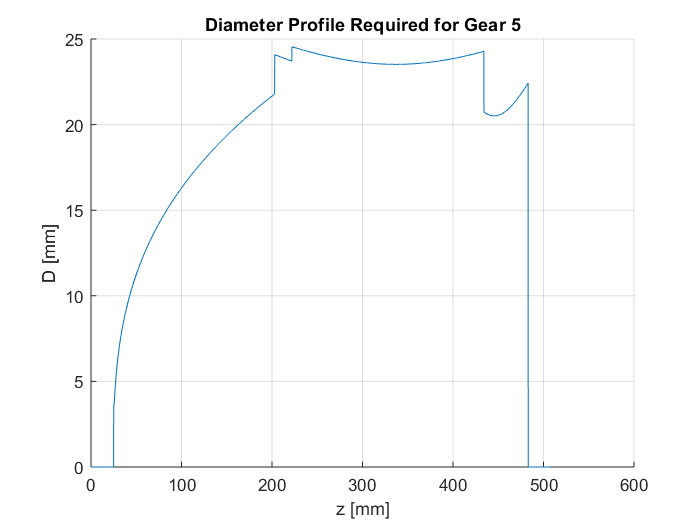

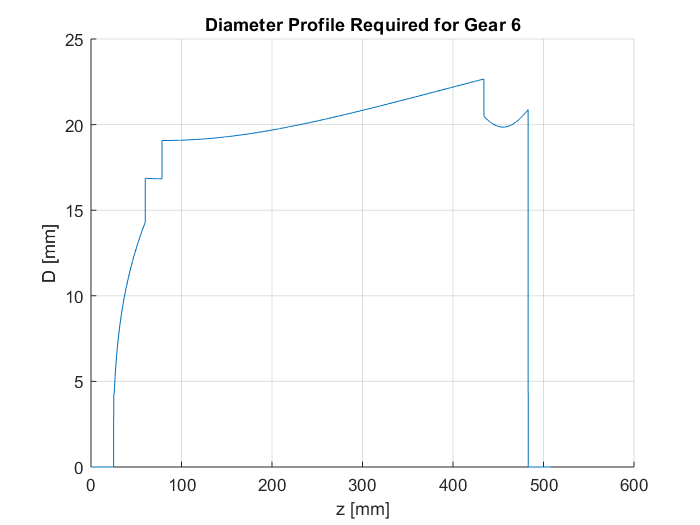

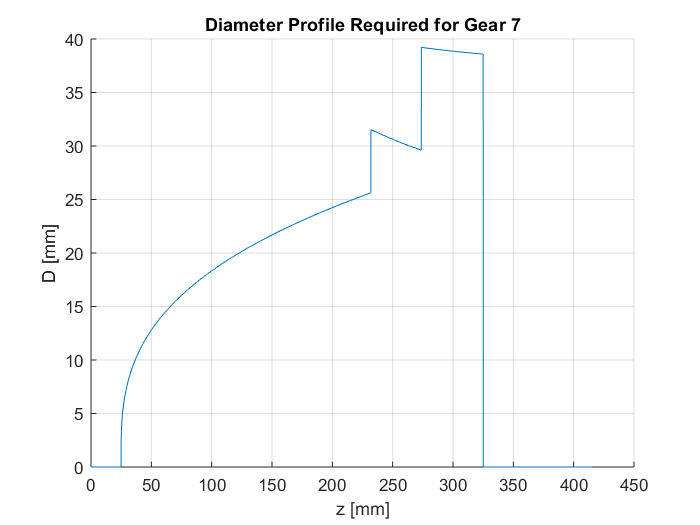

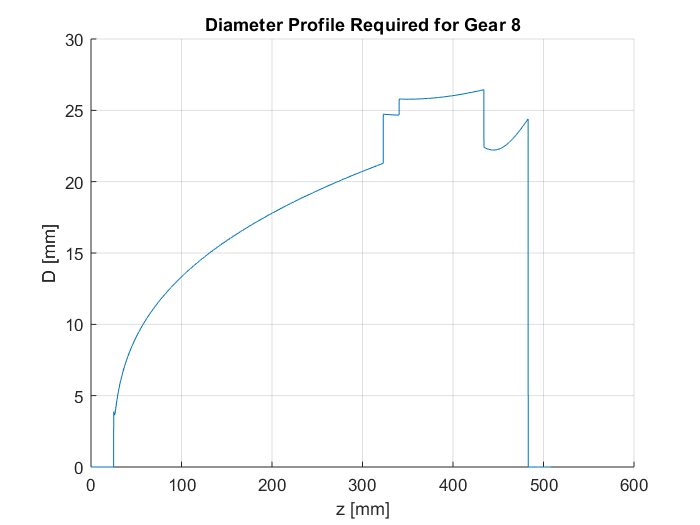

sigma_y = 780; % [MPa] - CrNiMo6
SF = 1.5; % [-] - Safety Factor
D = zeros(length(z2), 8, 2); % [mm] - Diameter Along Z
for k = 1:8
    figure(k+7)
    grid on
    hold on
   if k<4 || k==7
       for j = 1:length(z1)
           p = [pi^2*(sigma_y/SF)^2 0 0 0 -16*N(j, k, 1)^2 -256*N(j, k, 1)*Mf(j, k, 1) -256*(4*Mf(j, k, 1)^2+3*Mz(j, k, 1)^2)];
           d = roots(p);
           D(j, k, 1) = max(real(d(imag(d)==0 & real(d)>=0)));
       end
       plot(z1, D(1:length(z1), k, 1))
       xlabel('z [mm]')
       ylabel('D [mm]')
       title(['Diameter Profile Required for Gear ', num2str(k)])
   else
       for j = 101:length(z2)-100
           p = [pi^2*(sigma_y/SF)^2 0 0 0 -12*(N(j, k, 2)^2+3*Tf(j, k, 2)^2) -128*(N(j, k, 2)*Mf(j, k, 2)+3*Tf(j, k, 2)*Mz(j, k, 2)) -256*(4*Mf(j, k, 2)^2+3*Mz(j, k, 2)^2)];
           d = roots(p);
           D(j, k, 2) = real(min(d(imag(d)==0 & real(d)>=0)));
       end
       plot(z2, D(:, k, 2))
       xlabel('z [mm]')
       ylabel('D [mm]')
       title(['Diameter Profile Required for Gear ', num2str(k)])
   end
end

## Minimum Required Diameter

### Primary Shaft

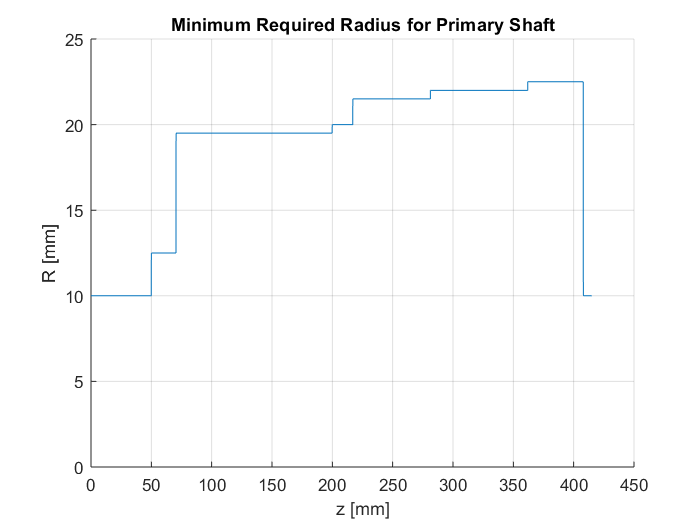

D1 = zeros(length(z1), 1);
D1(z1<Zc(2)-b(2)/2+25) = ceil(max(max(D(z1<Zc(2)-b(2)/2+25, :, 1))));
D1(z1>=Zc(2)-b(2)/2+25 & z1<Zc(2)+b(2)/2+25) = ceil(max(max(D(z1>=Zc(2)-b(2)/2+25 & z1<Zc(2)+b(2)/2+25, :, 1))));
D1(z1>=Zc(2)+b(2)/2+25 & z1<Zc(3)-b(3)/2+25) = ceil(max(max(D(z1>=Zc(2)+b(2)/2+25 & z1<Zc(3)+b(3)/2+25, :, 1))));
D1(z1>=Zc(3)-b(3)/2+25 & z1<Zc(3)+b(3)/2+25) = ceil(max(max(D(z1>=Zc(3)-b(3)/2+25 & z1<Zc(3)+b(3)/2+25, :, 1))));
D1(z1>=Zc(3)+b(3)/2+25 & z1<Zc(1)-b(1)/2+25) = ceil(max(max(D(z1>=Zc(3)+b(3)/2+25 & z1<Zc(1)-b(1)/2+25, :, 1))));
D1(z1>=Zc(1)-b(1)/2+25 & z1<Zc(1)+b(1)/2+25) = ceil(max(max(D(z1>=Zc(1)-b(1)/2+25 & z1<Zc(1)+b(1)/2+25, :, 1))));
D1(z1>=Zc(1)+b(1)/2+25 & z1<Zc(7)-b(7)/2+25) = ceil(max(max(D(z1>=Zc(1)+b(1)/2+25 & z1<Zc(7)-b(7)/2+25, :, 1))));
D1(z1>=Zc(7)-b(7)/2+25 & z1<Zc(7)+b(7)/2+25) = ceil(max(max(D(z1>=Zc(7)-b(7)/2+25 & z1<Zc(7)+b(7)/2+25, :, 1))));
D1(z1>=Zc(7)+b(7)/2+25 & z1<Zc(end-1)-b(end-1)/2+25) = ceil(max(max(D(z1>=Zc(7)+b(7)/2+25 & z1<Zc(end-1)-b(end-1)/2+25, :, 1))));
D1(z1>=Zc(end-1)-b(end-1)/2+25 & z1<Zc(end-1)+b(end-1)/2+25) = ceil(max(max(D(z1>=Zc(end-1)-b(end-1)/2+25 & z1<Zc(end-1)+b(end-1)/2+25, :, 1))));
D1(D1==0) = min(D1(D1~=0));
figure
hold on
grid on
xlabel('z [mm]')
ylabel('R [mm]')
title('Minimum Required Radius for Primary Shaft')
ylim([0 25])
plot(z1, D1/2)

### Shaft 2

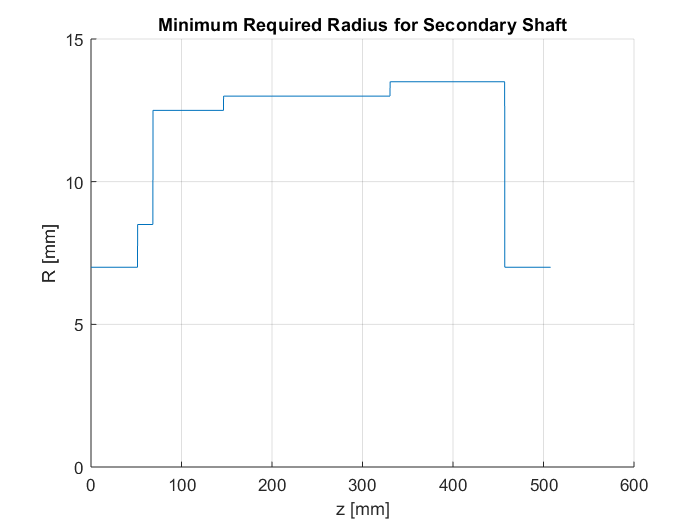

D2 = zeros(length(z2), 1);
D2(z2<Zc(6)-b(6)/2+25) = ceil(max(max(D(z2<Zc(6)-b(6)/2+25, :, 2))));
D2(z2>=Zc(6)-b(6)/2+25 & z2<Zc(6)+b(6)/2+25) = ceil(max(max(D(z2>=Zc(6)-b(6)/2+25 & z2<Zc(6)+b(6)/2+25, :, 2))));
D2(z2>=Zc(6)+b(6)/2+25 & z2<Zc(4)-b(4)/2+25) = ceil(max(max(D(z2>=Zc(6)+b(6)/2+25 & z2<Zc(4)+b(4)/2+25, :, 2))));
D2(z2>=Zc(4)-b(4)/2+25 & z2<Zc(4)+b(4)/2+25) = ceil(max(max(D(z2>=Zc(4)-b(4)/2+25 & z2<Zc(4)+b(4)/2+25, :, 2))));
D2(z2>=Zc(4)+b(4)/2+25 & z2<Zc(5)-b(5)/2+25) = ceil(max(max(D(z2>=Zc(4)+b(4)/2+25 & z2<Zc(5)-b(5)/2+25, :, 2))));
D2(z2>=Zc(5)-b(5)/2+25 & z2<Zc(5)+b(5)/2+25) = ceil(max(max(D(z2>=Zc(5)-b(5)/2+25 & z2<Zc(5)+b(5)/2+25, :, 2))));
D2(z2>=Zc(5)+b(5)/2+25 & z2<Zc(8)-b(8)/2+25) = ceil(max(max(D(z2>=Zc(5)+b(5)/2+25 & z2<Zc(8)-b(8)/2+25, :, 2))));
D2(z2>=Zc(8)-b(8)/2+25 & z2<Zc(8)+b(8)/2+25) = ceil(max(max(D(z2>=Zc(8)-b(8)/2+25 & z2<Zc(8)+b(8)/2+25, :, 2))));
D2(z2>=Zc(8)+b(8)/2+25 & z2<Zc(end)-b(end)/2+25) = ceil(max(max(D(z2>=Zc(8)+b(8)/2+25 & z2<Zc(end)-b(end)/2+25, :, 2))));
D2(z2>=Zc(end)-b(end)/2+25 & z2<Zc(end)+b(end)/2+25) = ceil(max(max(D(z2>=Zc(end)-b(end)/2+25 & z2<Zc(end)+b(end)/2+25, :, 2))));
D2(D2==0) = min(D2(D2~=0));
figure
hold on
grid on
xlabel('z [mm]')
ylabel('R [mm]')
title('Minimum Required Radius for Secondary Shaft')
ylim([0 15])
plot(z2, D2/2)

## Diameter Choice

### Primary Shaft

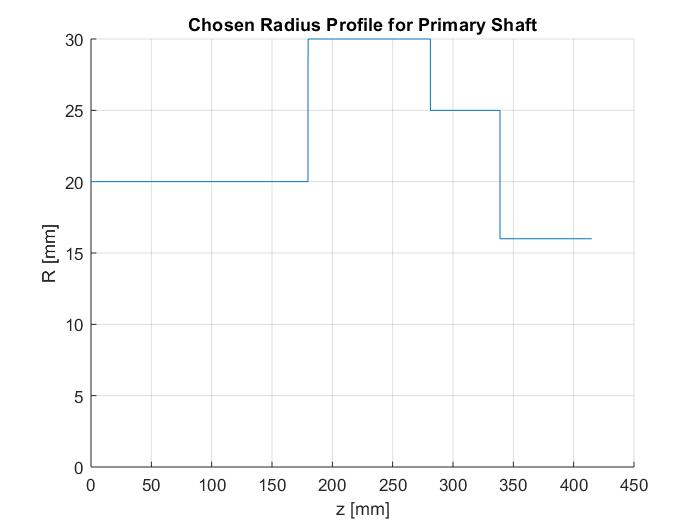

r1 = 20*ones(length(z1), 1); % [mm]
r1(z1>=Zc(3)-b(3)/2+25 & z1<=Zc(7)+b(7)/2+25) = 30;
r1(z1>Zc(7)+b(7)/2+25 & z1<Zc(end-1)-b(end-1)/2+25) = 25;
r1(z1>=Zc(end-1)-b(end-1)+25) = 16;
figure
hold on
grid on
xlabel('z [mm]')
ylabel('R [mm]')
ylim([0 30])
title('Chosen Radius Profile for Primary Shaft')
plot(z1, r1)

### Secondary Shaft

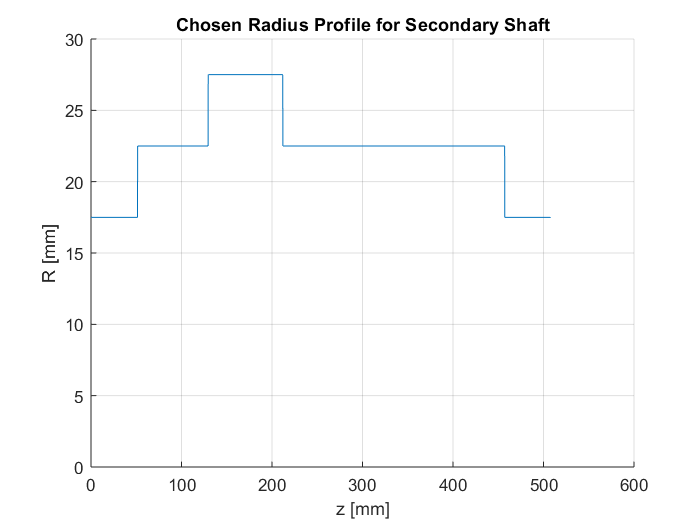

r2 = 17.5*ones(length(z2), 1); % [mm]
r2((z2>=Zc(6)-b(6)/2+25 & z2<Zc(4)-b(4)/2+25) | (z2>Zc(5)+b(5)/2+25 & z2<=Zc(end)+b(end)/2+25)) = 22.5; % [mm]
r2(z2>=Zc(4)-b(4)/2+25 & z2<=Zc(5)+b(5)/2+25) = 27.5; % [mm]
figure
hold on
grid on
xlabel('z [mm]')
ylabel('R [mm]')
ylim([0 30])
title('Chosen Radius Profile for Secondary Shaft')
plot(z2, r2)

## Static Verification

### Primary Shaft

This is done by calculating the safety factor along the axis of the shaft and when the first gear is engaged since it's the most loaded gear on the primary shaft according to the first 8 figures.

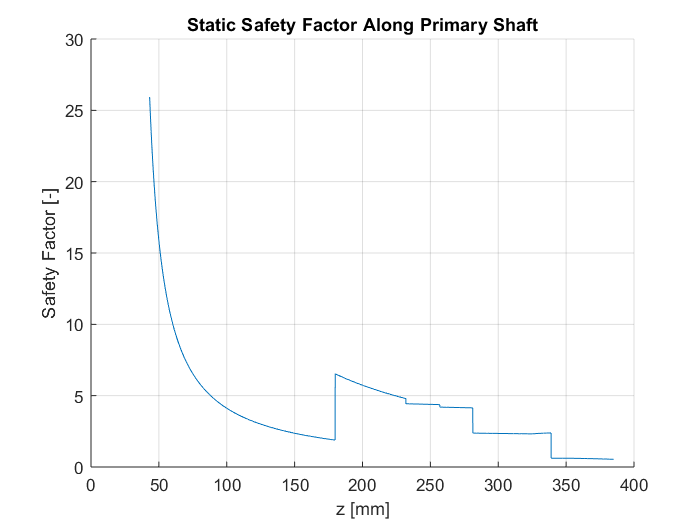

SF_S = zeros(length(z1), 1);
A = pi*(2*r1).^2/4; % [mm^2]
Wf = pi*(2*r1).^3/32; % [mm^3]
Wt = pi*(2*r1).^3/16; % [mm^3]
sigma_N = N(1:length(z1), 1, 1)./A; % [N/mm^2]
sigma_B = Mf(1:length(z1), 1, 1)./Wf; % [N/mm^2]
sigma_tot = sigma_N + sigma_B; % [N/mm^2]
tau_t = Mz(1:length(z1), 1, 1)./Wt; % [N/mm^2]
sigma_eq = sqrt(sigma_tot.^2 + 3*tau_t.^2); % [N/mm^2]
for j = 1:length(z1)
    if sigma_eq(j) >= 30
        SF_S(j) = sigma_y/sigma_eq(j);
    end
end
figure
grid on
title('Static Safety Factor Along Primary Shaft')
xlabel('z [mm]')
ylabel('Safety Factor [-]')
hold on
plot(z1(SF_S~=0), SF_S(SF_S~=0))

### Secondary Shaft

This is done by calculating the safety factor along the axis of the shaft and when the fourth gear is engaged since it's the most loaded gear on the primary shaft according to the first 8 figures.

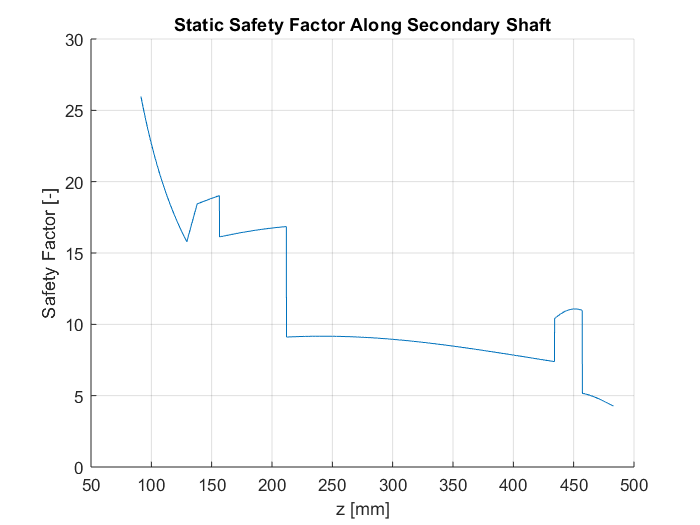

SF_S2 = zeros(length(z2), 1);
A = pi*(2*r2).^2/4;
Wf = pi*(2*r2).^3/32;
Wt = pi*(2*r2).^3/16;
sigma_N2 = N(1:length(z2), 4, 2)./A;
sigma_B2 = Mf(1:length(z2), 4, 2)./Wf;
sigma_tot = sigma_N2 + sigma_B2;
tau_t2 = Mz(1:length(z2), 4, 2)./Wt;
sigma_eq2 = sqrt(sigma_tot.^2 + 3*tau_t2.^2);
for j = 1:length(z2)
   if(sigma_eq2(j) >= 30)
       SF_S2(j) = sigma_y/sigma_eq2(j);
   end
end
figure
grid on
title('Static Safety Factor Along Secondary Shaft')
xlabel('z [mm]')
ylabel('Safety Factor [-]')
hold on
plot(z2(SF_S2~=0), SF_S2(SF_S2~=0))

## Fatigue Verification

As in the static verification, the most loaded cross section is the mid-plane of the final drive when the first gear is engaged. However, on the shoulder of the shaft right before that cross section, we have a fillet and thus a notch that could be more critical although the bending load is lower. Therefore, it's necessary to check and verify both of these cross sections.

To proceed with the verification of the cross section with a notch, we need to evaluate the stress concentration factor starting with notch sensitivity:


$$q=\frac{1}{1+\frac{A}{\sqrt{r}}}$$


where **A **is the square root of grain size and **r** is the notch radius.

Then we proceed by calculating the geometric stress raiser notch factor for normal, bending, and torsion loads according to the following figures:

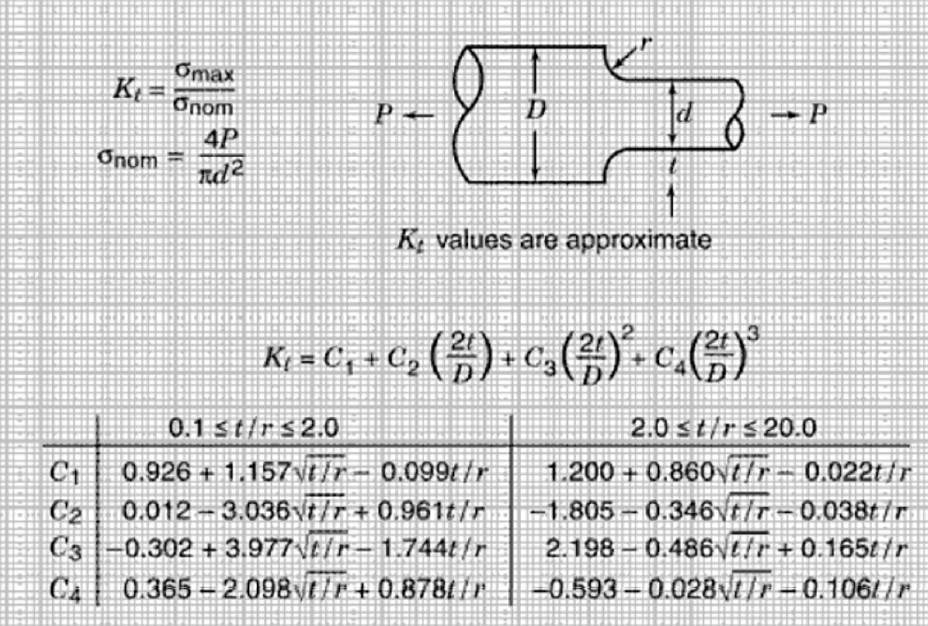             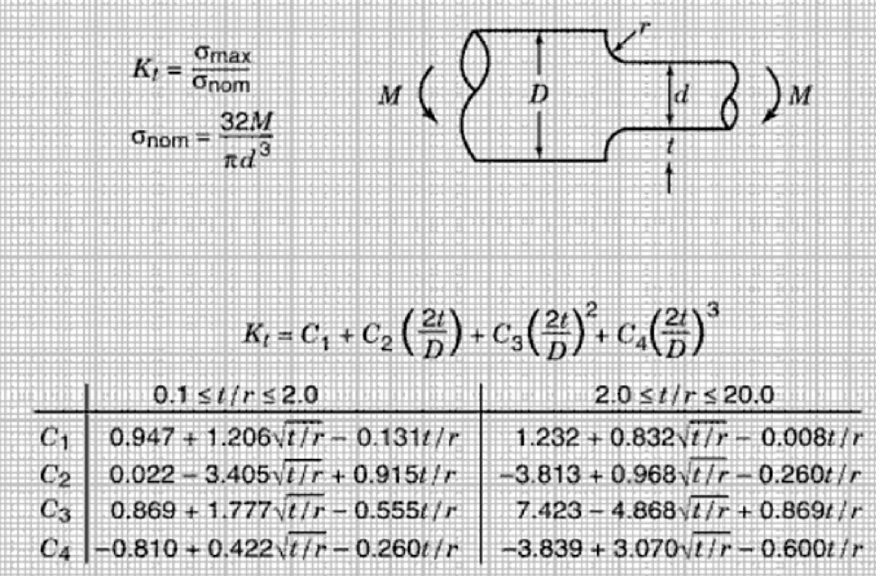             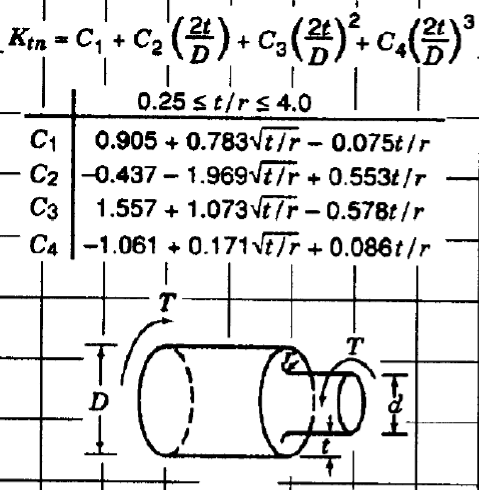

and then we can calculate the fatigue stress concentration factor for normal, bending, and torsion loads according to the following equation:


$$K_f =1+q*\left(K_t -1\right)$$


The calcuated factors are used to calculate the equivalent Von Mises mean and alternating stresses:

$\sigma_{a,\textrm{eq}} =\sqrt{{\left(K_f^N *\frac{\sigma_a^N }{0\ldotp 85}+K_f^B *\sigma_a^B \right)}^2 +3*{\left(K_f^T *\tau_a \right)}^2 \;}$    ;   $\sigma_{m,\textrm{eq}} =\sqrt{{\left(K_f^N *\sigma_m^N +K_f^B *\sigma_m^B \right)}^2 +3*{\left(K_f^T *\tau_m \right)}^2 }$

These two values allow us to locate our working point on the Haigh's diagram. Hence, at this point we need to calulcate the fatigue strength of the component. This is done by referring to the fatigue strength of the material and then calculating that of the component according to the following figures and equation:


$$\sigma_{D-1}^C =\sigma_{D-1} *C_s *C_L *C_F$$


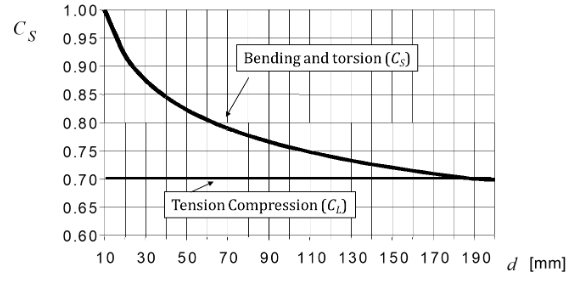                   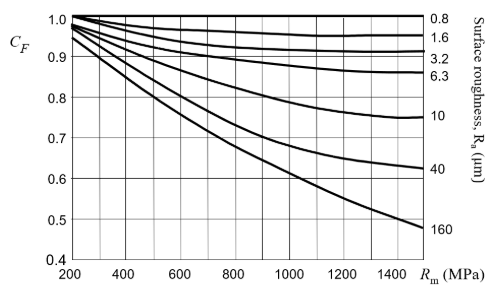

The last step before calculating the safety factor is calculating the fatigue strength of the component according to our working point using the Goodman Equation:


$$\left(\frac{\sigma_D^C }{\sigma_{D-1}^C }\right)+\left(\frac{\sigma_{m,\textrm{eq}} }{\sigma_{\textrm{ultimate}} }\right)=1$$


Eventually the safety factor can be calculated according to the following equation:


$$\textrm{SF}=\frac{\sigma_D^C }{\sigma_{a,\textrm{eq}} }$$


### Primary Shaft

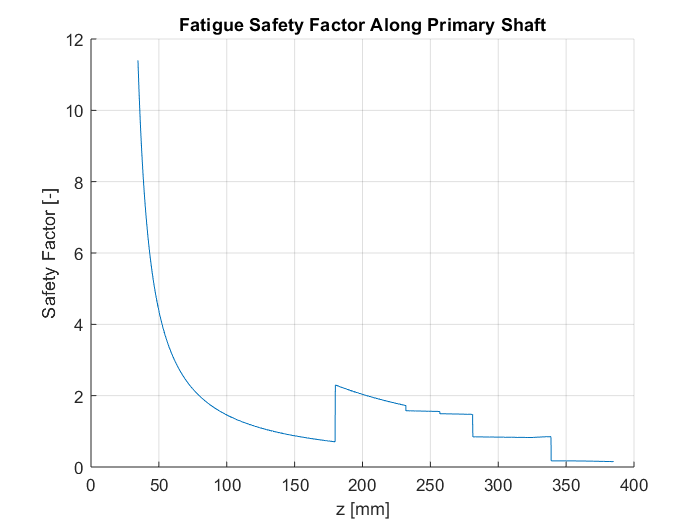

sigma_N_mean = sigma_N;
sigma_B_alt = sigma_B;
tau_t_mean = tau_t;
t = zeros(length(z1), 1);
t(z1==179.9) = 10;
t(z1==281.2) = 5;
t(z1==338.9) = 5;
r = 2.5; % [mm] - Fillet Radius
q = 1/(1+sqrt(5)/r); % Notch Sensitivity
C1_N = 1.2 + 0.86*sqrt(t/r) - 0.022*t/r;
C2_N = -1.805 + 0.346*sqrt(t/r) - 0.038*t/r;
C3_N = 2.198 - 0.486*sqrt(t/r) + 0.165*t/r;
C4_N = -0.593 - 0.028*sqrt(t/r) - 0.106*t/r;
Kt_N = C1_N + C2_N.*(t./r1) + C3_N.*(t./r1).^2 + C4_N.*(t./r1).^3;
Kf_N = 1 + q*(Kt_N - 1);

C1_B = 1.232 + 0.832*sqrt(t/r) - 0.008*t/r;
C2_B = -3.813 + 0.968*sqrt(t/r) - 0.26*t/r;
C3_B = 7.423 - 4.8698*sqrt(t/r) + 0.869*t/r;
C4_B = -3.839 + 3.07*sqrt(t/r) - 0.6*t/r;
Kt_B = C1_B + C2_B.*(t./r1) + C3_B.*(t./r1).^2 + C4_B.*(t./r1).^3;
Kf_B = 1 + q*(Kt_B - 1);

C1_T = 0.905 + 0.783*sqrt(t/r) - 0.075*t/r;
C2_T = -0.437 - 1.969*sqrt(t/r) + 0.553*t/r;
C3_T = 1.557 + 1.073*sqrt(t/r) - 0.578*t/r;
C4_T = -1.061 + 0.171*sqrt(t/r) + 0.086*t/r;
Kt_T = C1_T + C2_T.*(t./r1) + C3_T.*(t./r1).^2 + C4_T.*(t./r1).^3;
Kf_T = 1 + q*(Kt_T - 1);

sigma_alt_eq = Kf_B.*sigma_B_alt;
sigma_mean_eq = sqrt((Kf_N.*sigma_N_mean).^2 + 3*(Kf_T.*tau_t_mean).^2);
sigma_u = 980; % [MPa] - Ultimate Tensile Strength
sigma_Dm1 = 600; % [MPa] - Material Fatigue Strength
Cs = zeros(length(z1), 1);
Cs(r1==20) = 0.84;
Cs(r1==25) = 0.825;
Cs(r1==30) = 0.8; % [-] - Size and Bending/Torsion Factor
Cs(r1==16) = 0.875;
Cl = 0.7; % [-] - Size and Tension Factor
Cf = 1; % [-] Surfac Finish Factor
sigma_Dm1C = sigma_Dm1*Cs*Cl*Cf; % [MPa] - Component Fatigue Strength
sigma_D = sigma_Dm1C.*(1 - (sigma_mean_eq/sigma_u)); % [MPa] - Goodman Eqiation
SF_F = zeros(length(z1), 1);
for j = 1:length(z1)
    if sigma_alt_eq(j)>=30
        SF_F(j) = sigma_D(j)/sigma_alt_eq(j);
    end
end
figure
grid on
hold on
title('Fatigue Safety Factor Along Primary Shaft')
xlabel('z [mm]')
ylabel('Safety Factor [-]')
plot(z1(SF_F~=0), SF_F(SF_F~=0))

### Secondary Shaft

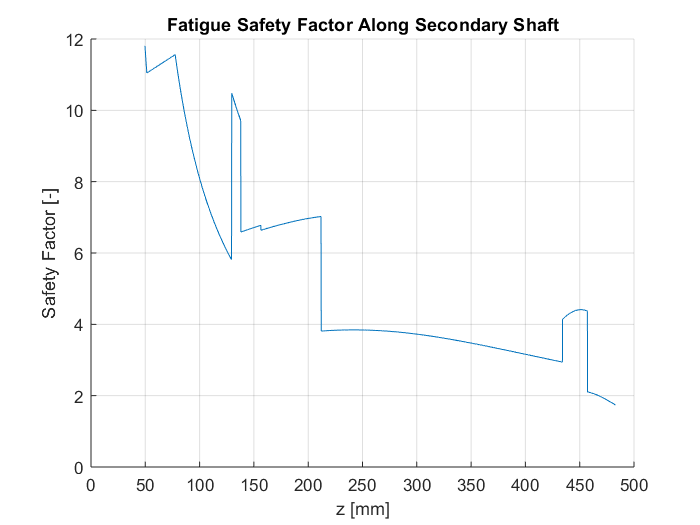

sigma_N_mean = sigma_N2;
sigma_B_alt = sigma_B2;
tau_t_mean = tau_t2;
t = zeros(length(z2), 1);
t(z2==51.5) = 5;
t(z2==129.5) = 5;
t(z2==211.9) = 5;
t(z2==457.1) = 5;
r = 2.5; % [mm] - Fillet Radius
q = 1/(1+sqrt(5)/r); % Notch Sensitivity
C1_N = 1.2 + 0.86*sqrt(t/r) - 0.022*t/r;
C2_N = -1.805 + 0.346*sqrt(t/r) - 0.038*t/r;
C3_N = 2.198 - 0.486*sqrt(t/r) + 0.165*t/r;
C4_N = -0.593 - 0.028*sqrt(t/r) - 0.106*t/r;
Kt_N = C1_N + C2_N.*(t./r2) + C3_N.*(t./r2).^2 + C4_N.*(t./r2).^3;
Kf_N = 1 + q*(Kt_N - 1);

C1_B = 1.232 + 0.832*sqrt(t/r) - 0.008*t/r;
C2_B = -3.813 + 0.968*sqrt(t/r) - 0.26*t/r;
C3_B = 7.423 - 4.8698*sqrt(t/r) + 0.869*t/r;
C4_B = -3.839 + 3.07*sqrt(t/r) - 0.6*t/r;
Kt_B = C1_B + C2_B.*(t./r2) + C3_B.*(t./r2).^2 + C4_B.*(t./r2).^3;
Kf_B = 1 + q*(Kt_B - 1);

C1_T = 0.905 + 0.783*sqrt(t/r) - 0.075*t/r;
C2_T = -0.437 - 1.969*sqrt(t/r) + 0.553*t/r;
C3_T = 1.557 + 1.073*sqrt(t/r) - 0.578*t/r;
C4_T = -1.061 + 0.171*sqrt(t/r) + 0.086*t/r;
Kt_T = C1_T + C2_T.*(t./r2) + C3_T.*(t./r2).^2 + C4_T.*(t./r2).^3;
Kf_T = 1 + q*(Kt_T - 1);
sigma_alt_eq = Kf_B.*sigma_B_alt;
sigma_mean_eq = sqrt((Kf_N.*sigma_N_mean).^2 + 3*(Kf_T.*tau_t_mean).^2);
Cs = zeros(length(z2), 1);
Cs(r2==17.5) = 0.85;
Cs(r2==22.5) = 0.83;
Cs(r2==27.5) = 0.82; % [-] - Size and Bending/Torsion Factor
Cl = 0.7; % [-] - Size and Tension Factor
Cf = 1; % [-] Surfac Finish Factor
sigma_Dm1C = sigma_Dm1*Cs*Cl*Cf; % [MPa] - Component Fatigue Strength
sigma_D = sigma_Dm1C.*(1 - (sigma_mean_eq/sigma_u)); % [MPa] - Goodman Eqiation
SF_F2 = zeros(length(z2), 1);
for j = 1:length(z2)
    if sigma_alt_eq(j)>=30
        SF_F2(j) = sigma_D(j)/sigma_alt_eq(j);
    end
end
figure
grid on
hold on
title('Fatigue Safety Factor Along Secondary Shaft')
xlabel('z [mm]')
ylabel('Safety Factor [-]')
plot(z2(SF_F2~=0), SF_F2(SF_F2~=0))